# Slosh 2D

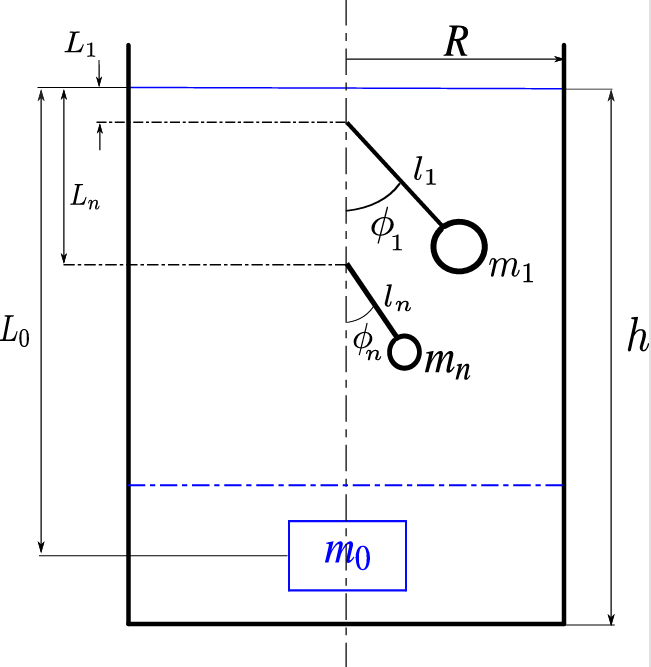

In this code the equation of motion for the pendulum angles representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent the 1D motion of the pivot, but it is the same for any point with a displacement along z of the cylinder axis.

clc 
clear all

syms theta(t)
syms t 
syms h l m g b
syms x(t) y z(t)

$\theta$ = second rotation about Y describing the sloshing

l = length of pendulum

m = mass of pendulum

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid mass in the world reference frame. 

### Homogeneous Transformation from inertial frame to pivot

% Second rotation about y (-theta for right hand rule, x pos on right, z
% pos up)
R_y_theta = [cos(-theta),  0,  sin(-theta);
              0,            1,            0;
             -sin(-theta),  0,  cos(-theta)];

R = R_y_theta

$$R(t) = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & 0 & -\sin\left(\theta \left(t\right)\right)\\ 0 & 1 & 0\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector

p = [x; y; z];

Define the transformation

T_wp = [R, p; 0 0 0 1];
T_wp = formula(T_wp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to pivot:');

Homogeneous Transformation Matrix from world to pivot:


disp(T_wp);

$$\left(\begin{array}{cccc} \cos\left(\theta \left(t\right)\right) & 0 & -\sin\left(\theta \left(t\right)\right) & x\left(t\right)\\ 0 & 1 & 0 & y\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**If **$R_y(\theta)$**:**


$$p_m =$$

$$\left(\begin{array}{c}
-l\,\sin \left(\theta \left(t\right)\right)\\
0\\
-l\;\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


**If **$R_y(-\theta)$**:**


$$p_m =$$

$$\left(\begin{array}{c}
l\,\sin \left(\theta \left(t\right)\right)\\
0\\
-l\;\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


### Homogeneous Transformation from pivot to mass

Define translation vector

p = [0; 0; -l];

Homogeneous transformation

T_pm = [eye(3), p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wp*T_pm;

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)+l\,\sin\left(\theta \left(t\right)\right)$$

ym = T_wm(2,4)

$$ym = y$$

zm = T_wm(3,4)

$$zm = z\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)$$


$$x_m =\;x\left(t\right)+l\,\sin \left(\theta \left(t\right)\right)$$



$$y_{m\;} =\;y$$



$$z_m =\;z\left(t\right)-l\,\cos \left(\theta \left(t\right)\right)$$


Pendulum mass wrt pivot

xr = xm - x

$$xr(t) = l\,\sin\left(\theta \left(t\right)\right)$$

yr = ym - y

$$yr = 0$$

zr = zm - z

$$zr(t) = -l\,\cos\left(\theta \left(t\right)\right)$$

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);


xr_dot = diff(xr, t);
yr_dot = diff(yr, t);
zr_dot = diff(zr, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m * xm_dot^2;
Tmx = simplify(Tmx)

$$Tmx = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmy = 0.5 * m * ym_dot^2;
Tmy = simplify(Tmy)

$$Tmy = 0$$

%disp(latex(Tmx))

Tmz = 0.5 * m * zm_dot^2;
Tmz = simplify(Tmz)

$$Tmz = \frac{m\,{\left(\frac{\partial }{\partial t}z\left(t\right)+l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz

$$Tm = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}z\left(t\right)+l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

T = Tm;

### Potential energy

%% Potential energy
Um = m * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m\,\left(z\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\right)$$


$$U=g\,m\,{\left(z\left(t\right)-l\,\cos \left(\theta \left(t\right)\right)\right)}$$


### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);

% v = l*theta_dot*cos(theta);
% D = b/2 *(v^2);

v2 = xr_dot^2 + yr_dot^2 + zr_dot^2

$$v2(t) = l^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$

D = b/2 *(v2);

% D = c/2 *(theta_dot^2);
D_dthetadot = diff(D, theta_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L);

% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta);

### Equation of motion

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

$$b\,l^{2}\,\frac{\partial }{\partial t}\theta \left(t\right)+l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,l\,m\,\sin\left(\theta \left(t\right)\right)$$

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

b\,l^2\,\frac{\partial }{\partial t} \theta \left(t\right)+l^2\,m\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)+l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)+g\,l\,m\,\sin\left(\theta \left(t\right)\right)



syms c_theta s_theta
syms theta_dot theta_ddot x_ddot z_ddot
eq_sub1 = subs(eqn_theta,[cos(theta(t)), sin(theta(t))],[c_theta s_theta]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(x(t),t),t),diff(diff(z(t),t),t)],[theta_ddot,x_ddot,z_ddot]);
eq_sub3 = subs(eq_sub2, diff(theta(t),t),theta_dot);
eq_sub3 = simplify(eq_sub3);

% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
eqn1 = isolate(eq_sub3 == 0, theta_ddot);
eqn1 = collect(eqn1, [x_ddot, z_ddot, g, theta_dot]);
disp(eqn1);

$$\ddot{\theta }=\left(-\frac{c_{\theta }}{l}\right)\,\ddot{x}+\left(-\frac{s_{\theta }}{l}\right)\,\ddot{z}+\left(-\frac{s_{\theta }}{l}\right)\,g+\left(-\frac{b}{m}\right)\,\dot{\theta }$$

disp(latex(eqn1));

\ddot{\theta }=\left(-\frac{c_{\theta }}{l}\right)\,\ddot{x}+\left(-\frac{s_{\theta }}{l}\right)\,\ddot{z}+\left(-\frac{s_{\theta }}{l}\right)\,g+\left(-\frac{b}{m}\right)\,\dot{\theta }



% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
% disp(eqn1);

**If **$R_y(\theta)$**:**


$$\ddot{\theta} =-\frac{b}{m}\,\dot{\theta} +\frac{1}{l_n }c_{\theta } \,\ddot{x} -\frac{1}{l_n }s_{\theta } \,\left(\ddot{z} +g\right)$$


**If **$R_y(-\theta)$**:**


$$\ddot{\theta} =-\frac{b}{m}\,\dot{\theta} -\frac{1}{l_n }c_{\theta } \,\ddot{x} -\frac{1}{l_n }s_{\theta } \,\left(\ddot{z} +g\right)$$


**Linearized**


$$\ddot{\theta} =-\frac{b}{m}\,\dot{\theta} \pm \frac{1}{l_n }\ddot{x} -\frac{1}{l_n }\left(\ddot{z} +g\right)\;\theta$$



$$\ddot{\theta} +2{\zeta \omega }_n \dot{\theta} +\omega_n^2 =\pm \frac{1}{l_n }\ddot{x} -\frac{1}{l_n }\ddot{z} \;\theta$$
